x = -1.0 : 0.001 : 2.0;
f=@(x)atan(x+2);
plot(x, f(x), 'b'); hold on; grid on; y = x; plot(x, y, 'black');

x0 = 0.0; % начальное приближение
x1 = f(x0);
x0A = x0;
x1A = x1;
eps = 0.00001; 
N = 100;
for i = 1 : N % делаем максимум 100 итераций
    if abs(x1 - x0) <= eps
        x0
        x1
        i
        break
    end
    x0 = x1;
    x1 = f(x0);
    
end

x0 = 1.2744

x1 = 1.2744

i = 6


% вывожу альфы, она стремится к 1
for i = 1 : N
    if abs(x1A - x0A) <= eps
        break
    end
    x0A = x1A;
    x1A = f(x0A);
    alpha = log(abs(x1A-x1))/log(abs(x0A-x1))
end

alpha = 2.3497

alpha = 1.5849

alpha = 1.3705

alpha = 1.2786

alpha = Inf

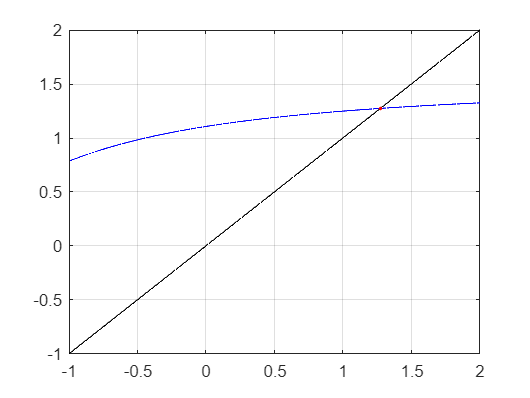


plot(x1,x1,'r.');